Con consigna positiva.

data_pos = load('motor_data\motor_real_control.mat')

data_pos = struct with fields:
    data: [1×1 Simulink.SimulationData.Dataset]



p = data_pos.data.getElement('p (deg):1').Values.Data;
pTime = data_pos.data.getElement('p (deg):1').Values.Time;
v = data_pos.data.getElement('v (deg//s):1').Values.Data;
vTime = data_pos.data.getElement('v (deg//s):1').Values.Time;
pEst = data_pos.data.getElement('pEst:1').Values.Data;
pEstTime = data_pos.data.getElement('pEst:1').Values.Time;
vEst = data_pos.data.getElement('vEst:1').Values.Data;
vEstTime = data_pos.data.getElement('vEst:1').Values.Time;
Vref = data_pos.data.getElement('Vref:1').Values.Data;
VrefTime = data_pos.data.getElement('Vref:1').Values.Time;

Representación

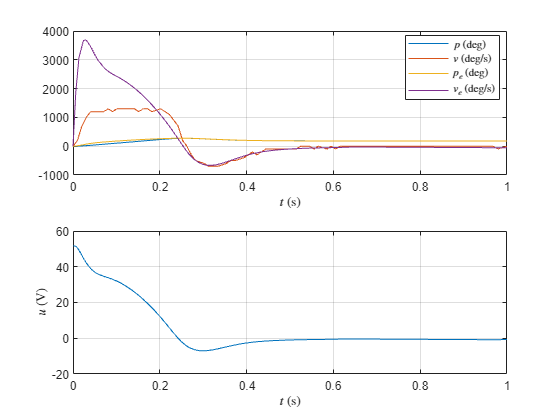

figure
subplot(2,1,1)
plot(pTime,p)
hold on
plot(vTime,v)
plot(pEstTime,pEst)
plot(vEstTime,vEst)
grid on
legend('$p$ (deg)','$v$ (deg/s)','$p_e$ (deg)','$v_e$ (deg/s)', Location="best", Interpreter='latex')
xlabel('$t$ (s)', Interpreter='latex')
xlim([0 1])
subplot(2,1,2)
plot(VrefTime,Vref)
grid on
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$u$ (V)', Interpreter='latex')
xlim([0 1])
exportgraphics(gcf,'figuras\controlRealPos.pdf')

Con consigna negativa.

data_neg = load('motor_data\motor_real_control_neg.mat')

data_neg = struct with fields:
    data: [1×1 Simulink.SimulationData.Dataset]


p = data_neg.data.getElement('p (deg):1').Values.Data;
pTime = data_neg.data.getElement('p (deg):1').Values.Time;
v = data_neg.data.getElement('v (deg//s):1').Values.Data;
vTime = data_neg.data.getElement('v (deg//s):1').Values.Time;
pEst = data_neg.data.getElement('pEst:1').Values.Data;
pEstTime = data_neg.data.getElement('pEst:1').Values.Time;
vEst = data_neg.data.getElement('vEst:1').Values.Data;
vEstTime = data_neg.data.getElement('vEst:1').Values.Time;
Vref = data_neg.data.getElement('Vref:1').Values.Data;
VrefTime = data_neg.data.getElement('Vref:1').Values.Time;

Representación

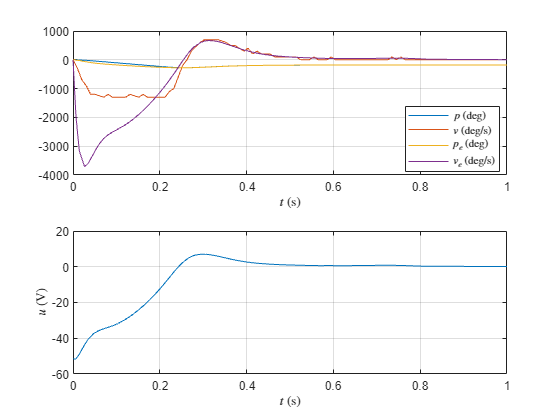

figure
subplot(2,1,1)
plot(pTime,p)
hold on
plot(vTime,v)
plot(pEstTime,pEst)
plot(vEstTime,vEst)
grid on
legend('$p$ (deg)','$v$ (deg/s)','$p_e$ (deg)','$v_e$ (deg/s)', Location="best", Interpreter='latex')
xlabel('$t$ (s)', Interpreter='latex')
xlim([0 1])
subplot(2,1,2)
plot(VrefTime,Vref)
grid on
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$u$ (V)', Interpreter='latex')
xlim([0 1])
exportgraphics(gcf,'figuras\controlRealNeg.pdf')